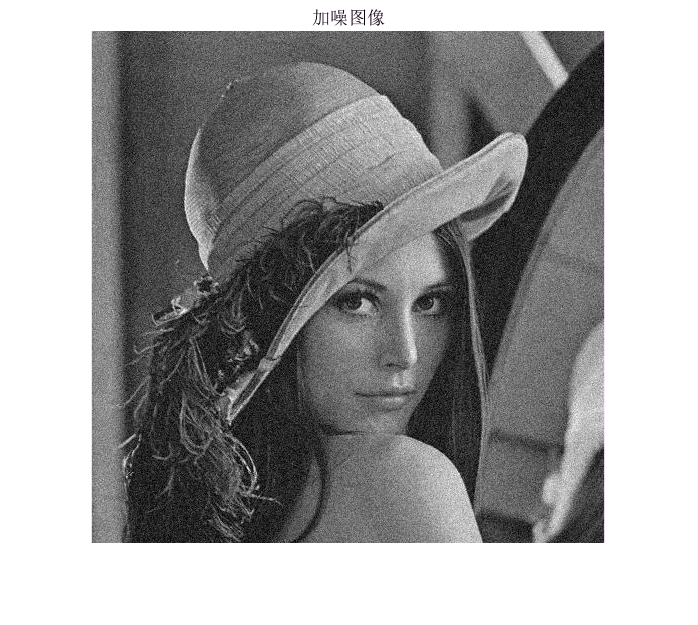

%空间滤波
I=imread('D:\matlab_project\image_process\WEEK6HW\exercise\lena.jpg');
imshow(I);title('加噪图像');

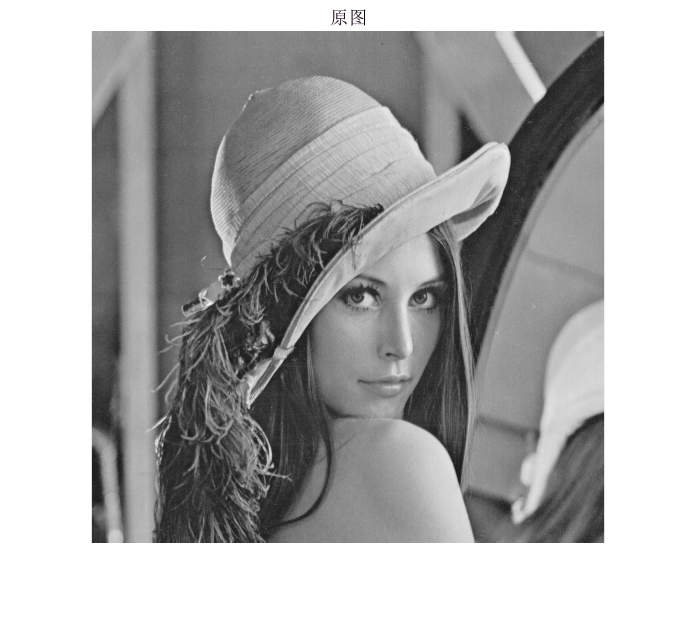

%原图
load('D:\matlab_project\image_process\WEEK6HW\exercise\lena512.mat');
old_I=uint8(lena512);
imshow(old_I);title('原图');

disp('带噪图像与原图的PSNR、MSE、SSIM');

带噪图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,I)

PSNR = 13.0734

MSE = 3.2044e+03

SSIM = 0.4500

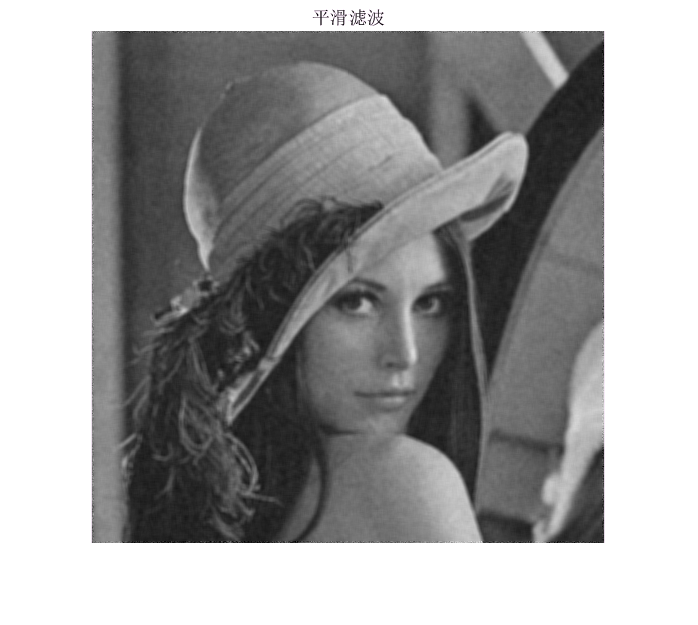

%低通滤波 平滑滤波 time:0.8s
new_I=mylvbo(I,'mean',2);
imshow(new_I);title('平滑滤波');

disp('均值滤波图像与原图的PSNR、MSE、SSIM');

均值滤波图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,new_I)

PSNR = 13.5808

MSE = 2.8510e+03

SSIM = 0.4883

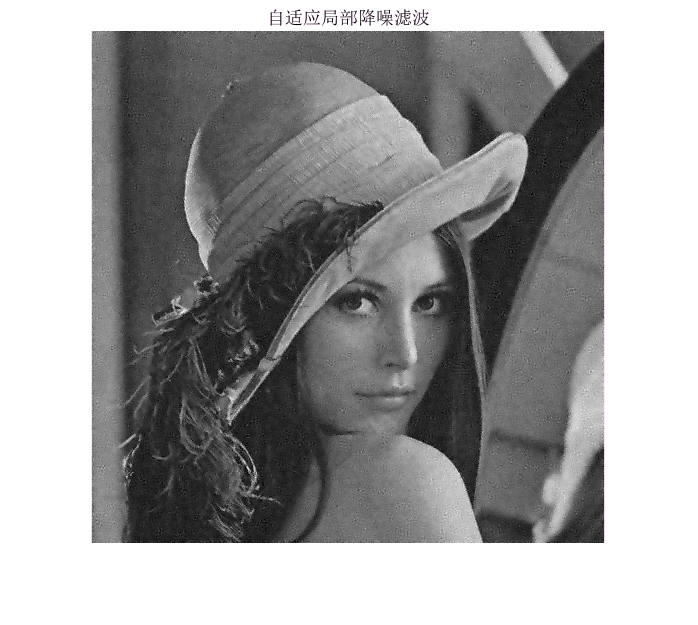

%自适应局部降噪滤波
new_I=mylvbo(I,'self_ad',[2 249]);%[sigma N]
imshow(new_I);title('自适应局部降噪滤波');

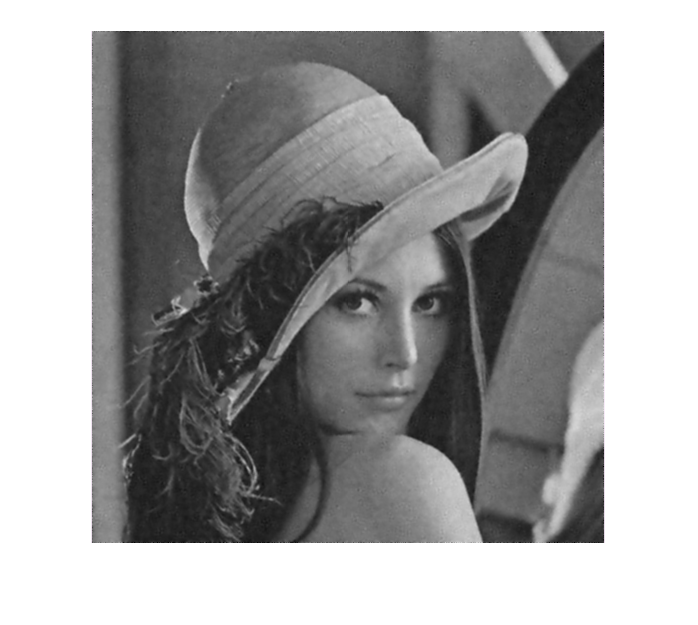

imshow(mylvbo(new_I,'guass',1));

disp('自适应局部降噪滤波图像与原图的PSNR、MSE、SSIM');

自适应局部降噪滤波图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,new_I)

PSNR = 13.4015

MSE = 2.9712e+03

SSIM = 0.4742

[PSNR,MSE,SSIM]=myevaluate(old_I,mylvbo(new_I,'guass',[1.2 1]))

PSNR = 13.5356

MSE = 2.8808e+03

SSIM = 0.4845

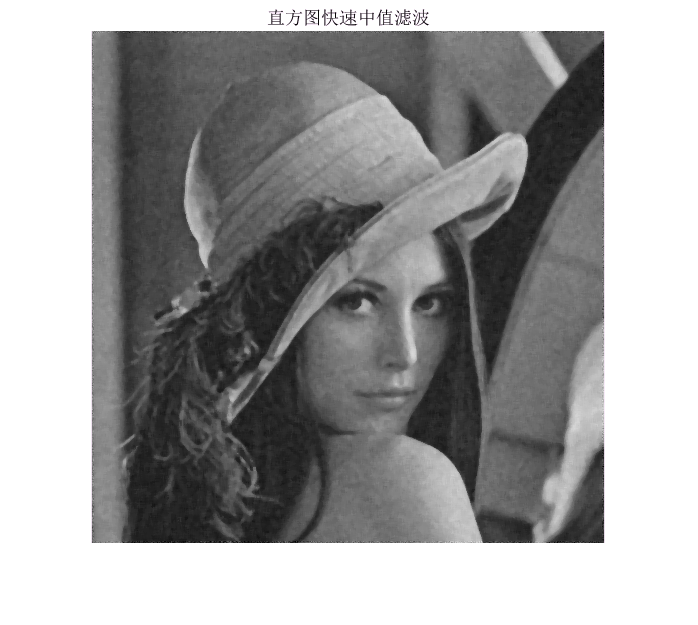

%低通滤波 高效的中值滤波，直方图实现 time:0.9s
new_I=mylvbo(I,'fmedian',2);
imshow(new_I);title('直方图快速中值滤波');

disp('中值滤波图像与原图的PSNR、MSE、SSIM');

中值滤波图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,new_I)

PSNR = 13.5118

MSE = 2.8966e+03

SSIM = 0.4852

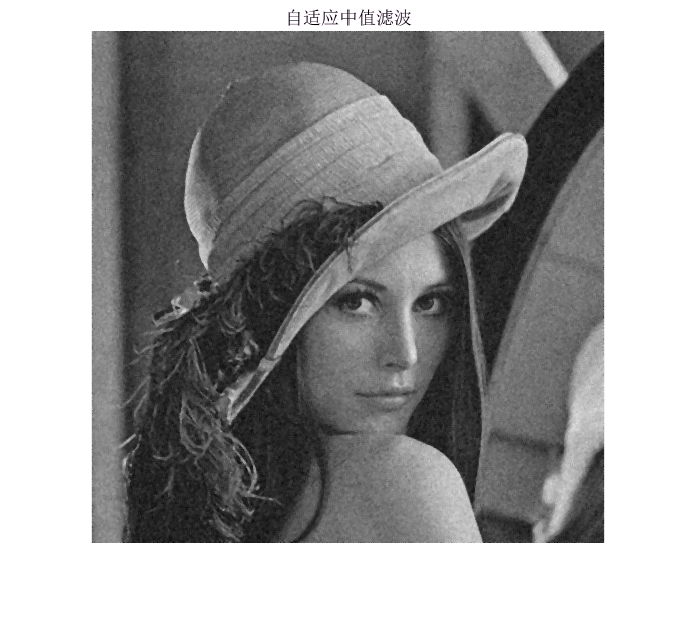

%自适应中值滤波
new_I=mylvbo(I,'self_me',[1 1]);%[begin max]
imshow(new_I);title('自适应中值滤波');

disp('自适应中值滤波图像与原图的PSNR、MSE、SSIM');

自适应中值滤波图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,new_I)

PSNR = 13.4194

MSE = 2.9590e+03

SSIM = 0.4768

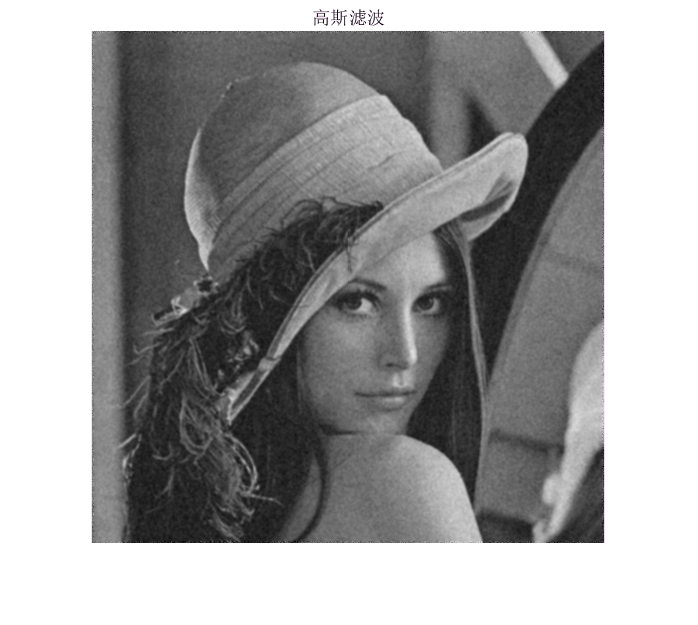

%加权滤波 高斯滤波
new_I=mylvbo(I,'guass',[1 2]);%[sigma N]
imshow(new_I);title('高斯滤波');

disp('高斯滤波图像与原图的PSNR、MSE、SSIM');

高斯滤波图像与原图的PSNR、MSE、SSIM


[PSNR,MSE,SSIM]=myevaluate(old_I,new_I)

PSNR = 13.4974

MSE = 2.9063e+03

SSIM = 0.4819